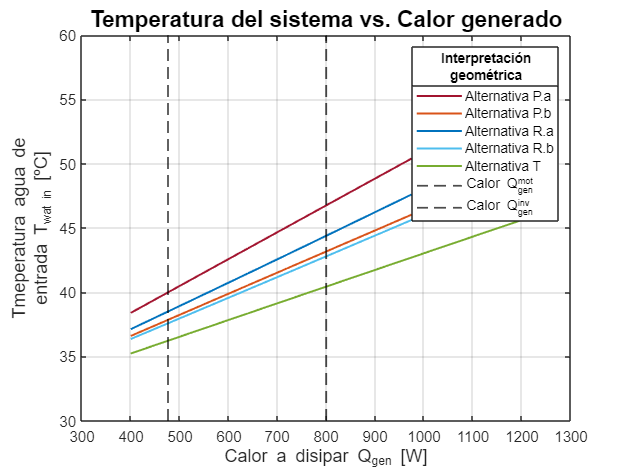

clc;clear;
close all;

T11=load("T_watin11.mat");
T12=load("T_watin12.mat");
T21=load("T_watin21.mat");
T22=load("T_watin22.mat");
T3=load("T_watin3.mat");
q_gen=load("Q_gen.mat");

T11=cell2mat(struct2cell(T11));
T12=cell2mat(struct2cell(T12));
T21=cell2mat(struct2cell(T21));
T22=cell2mat(struct2cell(T22));
T3=cell2mat(struct2cell(T3));
q_gen=cell2mat(struct2cell(q_gen));


plot(q_gen,T11,"LineWidth",1.3,"Color",[0.6350 0.0780 0.1840])
hold on;

plot(q_gen,T12,"LineWidth",1.3,"Color",[0.8500 0.3250 0.0980])
plot(q_gen,T21,"LineWidth",1.3,"Color",[0 0.4470 0.7410])
plot(q_gen,T22,"LineWidth",1.3,"Color",[0.3010 0.7450 0.9330])
plot(q_gen,T3,"LineWidth",1.3,"Color",[0.4660 0.6740 0.1880])
xline(799.92,"k--","LineWidth",1.2)
xline(476.14,"k--","LineWidth",1.2)

grid on;

legend('Alternativa P.a','Alternativa P.b','Alternativa R.a','Alternativa R.b','Alternativa T','Calor Q_{gen}^{mot}','Calor Q_{gen}^{inv}')
leg = legend('show'); % Just one output here
title(leg,{'Interpretación','geométrica'})

xlabel("Calor a disipar Q_{gen} [W]","FontSize",12);
ylabel(["Tmeperatura agua de","entrada T_{wat in} [ºC]"],"FontSize",12);
title("Temperatura del sistema vs. Calor generado","FontSize",15);
axis([300 1300 30 60])
%text(600,54,{'NOTA:','Radiador arbitrario'})
hold off;

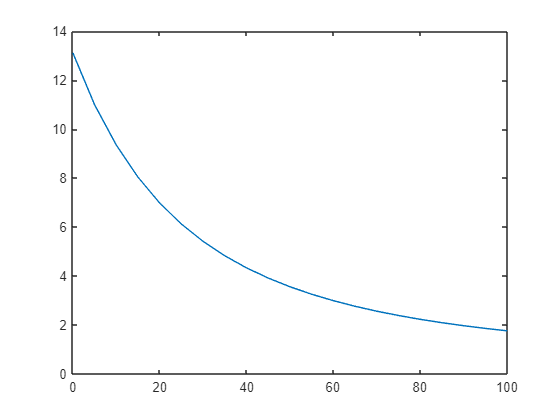

load("RE_CS_220901_APropiedadesAgua.mat")
plot(B(:,1),B(:,9))